close all
clc

syms b d1 d2 d3 d4 d5 d6 d7 d8 m
syms beta eta tau lambda k p
syms u_va u_1 u_2 u_p
syms sigma_1 sigma_2 sigma_6
syms gamma_1 gamma_2 gamma_3
syms rho_1 rho_2
syms lambda_1 lambda_2 lambda_3 lambda_4 lambda_5 lambda_6 lambda_7 lambda_8

syms S E Ia Q I1 I2 R V
syms alpha_1 delta_1 delta_2 delta_3 delta_4

% step=1;

% t=1:step:10;

% S = zeros(1, length(t));
% E = zeros(1, length(t));
% Ia = zeros(1, length(t));
% Q = zeros(1, length(t));
% I1 = zeros(1, length(t));
% I2 = zeros(1, length(t));
% R = zeros(1, length(t));
% V = zeros(1, length(t));
% T = zeros(1, length(t));

StateVar = [S E Ia Q I1 I2 R V];
%S(i+1) = S(i)+step*(b-(+d1+beta*Ia(i)*(1-u_p)+u_va)*S(i)+eta*R(i));
%E(i+1) = E(i)+step*(beta*Ia(i)*(1-u_p)*S(i)-(d2+k)*E(i));
%Ia(i+1) = Ia(i)+step*(-(d3+lambda*tau+gamma_1)*Ia(i)+k*E(i));
%Q(i+1) = Q(i)+step*(-(d4+gamma_2+sigma_1)*Q(i)+p*lambda*tau*Ia(i));
%I1(i+1) = I1(i)+step*(-(d5+gamma_3+rho_1*u_1+sigma_2*(1-u_1))*I1(i)+sigma_1*Q(i)+(1-p)*lambda*tau*Ia(i));
%I2(i+1) = I2(i)+step*(-(d6+m+rho_2*u_2)*I2(i)+sigma_2*(1-u_1)*I1(i));
%R(i+1) = R(i)+step*(-(eta+d7)*R(i)+gamma_1*Ia(i)+gamma_2*Q(i)+(gamma_3+rho_1*u_1)*I1(i)+rho_2*u_2*I2(i));
%V(i+1) = V(i)+step*(-d8*V(i)+u_va*S(i));
%System=[S(i+1) E(i+1) Ia(i+1),Q(i+1),I1(i+1),I2(i+1),R(i+1),V(i+1)];

System = [(b - (+d1 + beta * Ia * (1 - u_p) + u_va) * S + eta * R )
    (beta * Ia * (1 - u_p) * S - (d2 + k) * E)
    (-(d3 + lambda * tau + gamma_1) * Ia + k * E)
    (-(d4 + gamma_2 + sigma_1) * Q + p * lambda * tau * Ia)
    (-(d5 + gamma_3 + rho_1 * u_1 + sigma_2 * (1 - u_1)) * I1 + sigma_1 * Q + (1 - p) * lambda * tau * Ia)
    (-(d6 + m + rho_2 * u_2) * I2 + sigma_2 * (1 - u_1) * I1)
    (-(eta + d7) * R + gamma_1 * Ia + gamma_2 * Q + (gamma_3 + rho_1 * u_1) * I1 + rho_2 * u_2 * I2)
    (-d8 * V + u_va * S)];
display(System);

$$System = \left(\begin{array}{c} b+R\,\eta -S\,\left(d_{1}+u_{\mathrm{va}}-\mathrm{Ia}\,\beta \,\left(u_{p}-1\right)\right)\\ -\text{E}\,\left(d_{2}+k\right)-\mathrm{Ia}\,S\,\beta \,\left(u_{p}-1\right)\\ \text{E}\,k-\mathrm{Ia}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)\\ \mathrm{Ia}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)\\ Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\mathrm{Ia}\,\lambda \,\tau \,\left(p-1\right)\\ -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)\\ \mathrm{Ia}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}\\ S\,u_{\mathrm{va}}-V\,d_{8} \end{array}\right)$$

%StateVar = [S E Ia Q I1 I2 R V];%
%Matrix=sym('zero',[8 8]);
Matrix=[[-(d1 + beta * Ia * (1 - u_p) + u_va ), 0, 0, 0, 0, 0, eta, 0],;
    [(beta * Ia * (1 - u_p)), - (d2 + k), 0, 0, 0, 0, 0, 0],;
    [0, 0, (-(d3 + lambda * tau + gamma_1)),0,0,0,0,0 ],;
    [0, 0, (p * lambda * tau), (-(d4 + gamma_2 + sigma_1)),0 ,0 ,0 ,0 ],;
    [0, 0, 0, sigma_1, -(d5 + gamma_3 + rho_1 * u_1 + sigma_2 * (1 - u_1)),(rho_2 * u_2),0,0  ],;
    [0,0,0,0,sigma_2 * (1 - u_1) ,-(d6 + m + rho_2 * u_2),0,0],;
    [0,0,gamma_1,gamma_2,(gamma_3 + rho_1 * u_1),rho_2 * u_2,-(eta + d7),0],;
    [u_va,0,0,0,0,0,0,-d8]];
display(Matrix);

$$Matrix = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{1}-u_{\mathrm{va}}-d_{1} & 0 & 0 & 0 & 0 & 0 & \eta & 0\\ -\sigma_{1} & -d_{2}-k & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -d_{3}-\gamma_{1}-\lambda \,\tau & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \lambda \,p\,\tau & -d_{4}-\gamma_{2}-\sigma_{1} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \sigma_{1} & \sigma_{2}\,\left(u_{1}-1\right)-\gamma_{3}-\rho_{1}\,u_{1}-d_{5} & \rho_{2}\,u_{2} & 0 & 0\\ 0 & 0 & 0 & 0 & -\sigma_{2}\,\left(u_{1}-1\right) & -d_{6}-m-\rho_{2}\,u_{2} & 0 & 0\\ 0 & 0 & \gamma_{1} & \gamma_{2} & \gamma_{3}+\rho_{1}\,u_{1} & \rho_{2}\,u_{2} & -d_{7}-\eta & 0\\ u_{\mathrm{va}} & 0 & 0 & 0 & 0 & 0 & 0 & -d_{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Ia}\,\beta \,\left(u_{p}-1\right) \end{array}$$






lambda_0 = 1;

length(System);

Lambda = [lambda_1, lambda_2, lambda_3, lambda_4, lambda_5, lambda_6, lambda_7, lambda_8];

L = alpha_1 * S + (1/2) * (delta_1 * u_p^2 + delta_2 * u_1^2 + delta_3 * u_2^2 + delta_4 * u_va^2);

%array delle derivate
Derivate_sys = [k, k, k, k, k, k, k];
Derivate_lambda=[k, k, k, k, k, k, k];
Derivate_control=[k,k,k,k];
%array 
Control = [u_p,u_1,u_2,u_va];
StateVar;
Lambda;
System;

H = lambda_0 * L + Lambda * System;

for elem = 1:length(System)
    display((System(elem)),char(StateVar(elem)));
end

$$S = b+R\,\eta -S\,\left(d_{1}+u_{\mathrm{va}}-\mathrm{Ia}\,\beta \,\left(u_{p}-1\right)\right)$$

$$E = -\text{E}\,\left(d_{2}+k\right)-\mathrm{Ia}\,S\,\beta \,\left(u_{p}-1\right)$$

$$Ia = \text{E}\,k-\mathrm{Ia}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$Q = \mathrm{Ia}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$I1 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\mathrm{Ia}\,\lambda \,\tau \,\left(p-1\right)$$

$$I2 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$R = \mathrm{Ia}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$V = S\,u_{\mathrm{va}}-V\,d_{8}$$

disp(' ');

%costate eq
for elem = 1:length(System)
    Derivate_sys(elem) = diff(H, StateVar(elem));
    display((Derivate_sys(elem)),strcat('D_',char(StateVar(elem))));
end

$$D\_S = \alpha_{1}+\lambda_{8}\,u_{\mathrm{va}}-\lambda_{1}\,\left(d_{1}+u_{\mathrm{va}}-\mathrm{Ia}\,\beta \,\left(u_{p}-1\right)\right)-\mathrm{Ia}\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)$$

$$D\_E = k\,\lambda_{3}-\lambda_{2}\,\left(d_{2}+k\right)$$

$$D\_Ia = \gamma_{1}\,\lambda_{7}-\lambda_{3}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)+\lambda \,\lambda_{4}\,p\,\tau +S\,\beta \,\lambda_{1}\,\left(u_{p}-1\right)-S\,\beta \,\lambda_{2}\,\left(u_{p}-1\right)-\lambda \,\lambda_{5}\,\tau \,\left(p-1\right)$$

$$D\_Q = \gamma_{2}\,\lambda_{7}+\lambda_{5}\,\sigma_{1}-\lambda_{4}\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_I1 = \lambda_{7}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-\lambda_{5}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\lambda_{6}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_I2 = \lambda_{7}\,\rho_{2}\,u_{2}-\lambda_{6}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)$$

$$D\_R = \eta \,\lambda_{1}-\lambda_{7}\,\left(d_{7}+\eta \right)$$

$$D\_V = -d_{8}\,\lambda_{8}$$

disp(' ');

for elem = 1:length(Lambda)
    Derivate_lambda(elem) = diff(H, Lambda(elem));
    display((Derivate_lambda(elem)),strcat('D_',char(Lambda(elem))));
end

$$D\_lambda\_1 = b+R\,\eta -S\,\left(d_{1}+u_{\mathrm{va}}-\mathrm{Ia}\,\beta \,\left(u_{p}-1\right)\right)$$

$$D\_lambda\_2 = -\text{E}\,\left(d_{2}+k\right)-\mathrm{Ia}\,S\,\beta \,\left(u_{p}-1\right)$$

$$D\_lambda\_3 = \text{E}\,k-\mathrm{Ia}\,\left(d_{3}+\gamma_{1}+\lambda \,\tau \right)$$

$$D\_lambda\_4 = \mathrm{Ia}\,\lambda \,p\,\tau -Q\,\left(d_{4}+\gamma_{2}+\sigma_{1}\right)$$

$$D\_lambda\_5 = Q\,\sigma_{1}-I_{1}\,\left(d_{5}+\gamma_{3}+\rho_{1}\,u_{1}-\sigma_{2}\,\left(u_{1}-1\right)\right)-\mathrm{Ia}\,\lambda \,\tau \,\left(p-1\right)$$

$$D\_lambda\_6 = -I_{2}\,\left(d_{6}+m+\rho_{2}\,u_{2}\right)-I_{1}\,\sigma_{2}\,\left(u_{1}-1\right)$$

$$D\_lambda\_7 = \mathrm{Ia}\,\gamma_{1}+Q\,\gamma_{2}+I_{1}\,\left(\gamma_{3}+\rho_{1}\,u_{1}\right)-R\,\left(d_{7}+\eta \right)+I_{2}\,\rho_{2}\,u_{2}$$

$$D\_lambda\_8 = S\,u_{\mathrm{va}}-V\,d_{8}$$




fprintf('Press Enter to plot some covid-19 data')

Press Enter to plot some covid-19 data

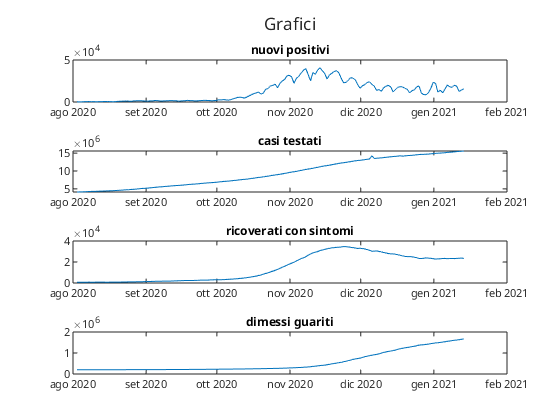

%pause


online_data=1;

if online_data==1
    fname='dati_covid.csv';
    websave(fname, 'https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv');
    %opts= detectImportOptions(fname,"VariableNamesLine",1)
    TableReal=readtable(fname);
    %elseif online_data==2
    %Table=readtable('andamento_covid.csv');
end
if online_data==1
    %convert data from cell(string) to datetime
    
    TableReal(1:160,:)=[];
    TableReal.data=datetime(TableReal.data,"InputFormat","uuuu-MM-dd'T'HH:mm:ss","Format","uuuu-MM-dd");
    len=height(TableReal);
    initTime=TableReal.data(1);
    
 
    Figura=tiledlayout(4,1);
    title(Figura,'Grafici');
    nexttile;
    plot(TableReal.data,TableReal.nuovi_positivi);
    title('nuovi positivi');
    nexttile;
    plot(TableReal.data,TableReal.casi_testati);
    title('casi testati');
    nexttile;
    plot(TableReal.data,TableReal.ricoverati_con_sintomi);
    title('ricoverati con sintomi');
    nexttile;
    plot(TableReal.data,TableReal.dimessi_guariti);
    title('dimessi guariti');
    
%    f= fit(datenum(Table.data),Table.casi_testati,'poly6');
    
end


% create the modelled evolution table

TableModelled=table('Size',[30 9],'VariableTypes',{'datetime','double','double','double','double','double','double','double','double'});

TableModelled.Properties.VariableNames=["date","S" ,"E" ,"Ia" ,"Q" ,"I1" ,"I2" ,"R", "V"];

TotalPopulation=60000000;
TotalPopulation=TotalPopulation-table2array(TableReal(1,"totale_positivi"));
TableModelled.date=datetime(TableModelled.date,"Format","uuuu-MM-dd");
TableModelled(1,:)={'2020-07-23',TotalPopulation,60000,30000,table2array(TableReal(1,"isolamento_domiciliare")),table2array(TableReal(1,"ricoverati_con_sintomi")),table2array(TableReal(1,"terapia_intensiva")),30000,0};


